#### 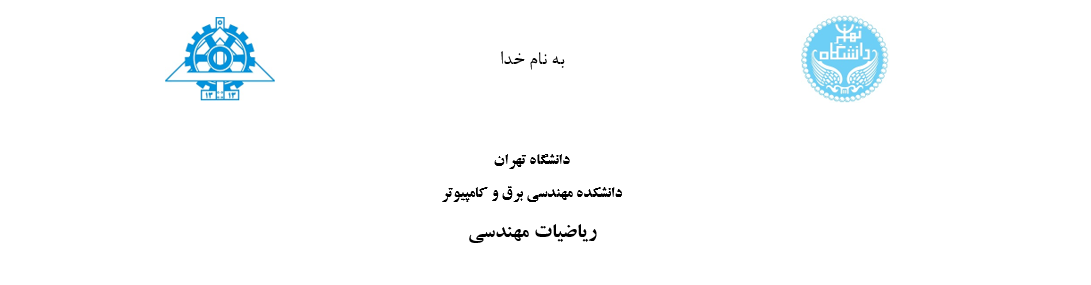

###      گزارش تمرین کامپیوتری 1

علی کرامتی

810198519

هشتم خرداد 1400

#### سوال اول-آشنایی با نرم افزار متلب

فرکانس نمونه برداری برابر تعداد واحد های نمونه برداری در یک ثانیه است. سیگنال های موجود در واقعیت به صورت گسسته هستند و این بینایی ماست که ان هارا به صورت پیوسته میبیند. در واقع چشم ما با توجه به نمونه برداری که انجام می دهد و مغز ما تصویر را پردازش می کند. در حالی که همین سیگنال یا تصویر توسط دستگاه دیگری که دقت بالایی دارد گسسته تحلیل می شود. بنابراین می توان گفت هرچه فرکانس نمونه برداری بیشتر باشد دقت بیشتر و نمونه برداری بیشتری داریم.

به صورت زیر است $y = cos(2\pi ft)$:

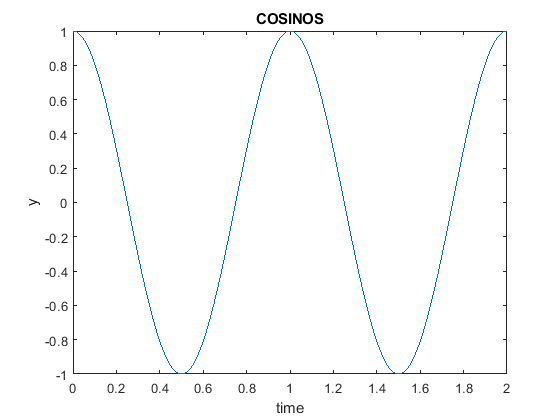

f = 1;
time_step = 0.0005;
t = 0:time_step:2;
y = cos(2*pi*t*f);

plot(t, y)
title COSINOS
xlabel time
ylabel y

تبدیل فوریه اش به صورت زیر است $y = cos(2\pi ft)$:

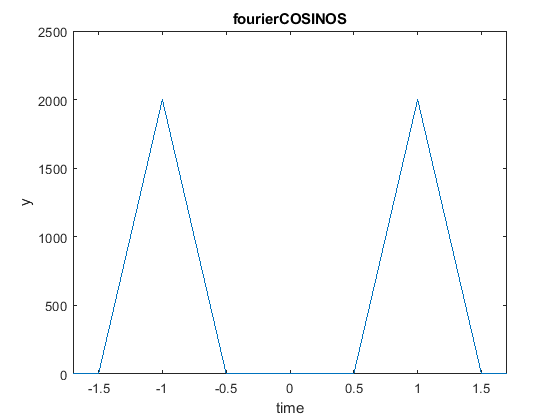

fs = 1 / time_step;
f_Fourier = linspace(-fs / 2, fs / 2, numel(y));
y_Fourier = fft(y);
y_shift = fftshift(y_Fourier);
plot(f_Fourier, abs(y_shift));
title fourierCOSINOS
xlabel time
ylabel y
xlim([-1.7, 1.7])

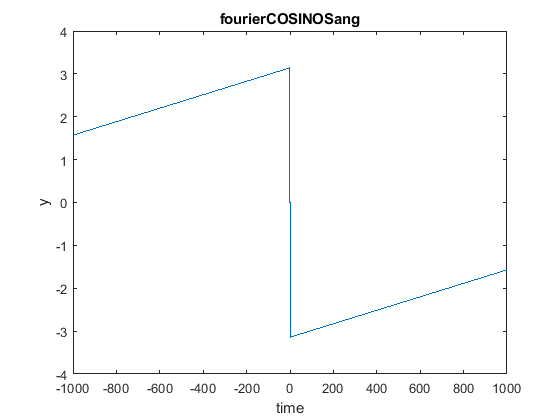


plot(f_Fourier, angle(y_shift));
title fourierCOSINOSang
xlabel time
ylabel y

تبدیل فوریه به صورت دستی به صورت زیر است $y = cos(2\pi ft)$

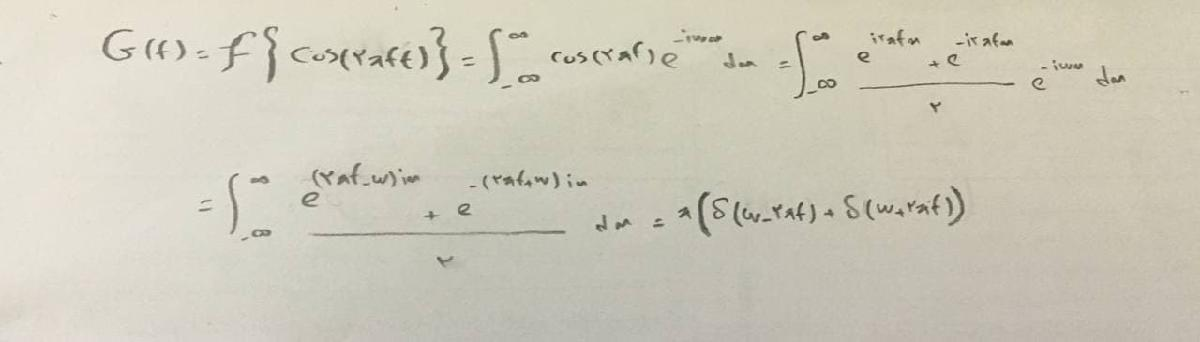

بردار فرکانس زا با استفاده از تایع

linspace

می سازیم. که بین دو فرکانس 

fs/2 and -fs/2 

می باشد. همچنین اندازه تابع نیز ارپومان آخر است.

## سوال دوم-پردازش وضعیت خواب

در هر ساعت سیکل خواب بچه 53 بار تکمیل میشود

1/1.3 = f

cd(fileparts(matlab.desktop.editor.getActiveFilename))
cd 'C:\Data\EEG Sleep Cycle'
read = load("data.mat")

read = struct with fields:
    data: {1×107 cell}


curr_data = read.data

curr_data = 1×107 cell array
    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'ah'}    {'tr'}    {'ah'}    {'ah'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'tr'}    {'ah'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'tr'}    {'qh'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'} 

my_data = 1 : numel(curr_data)

my_data =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


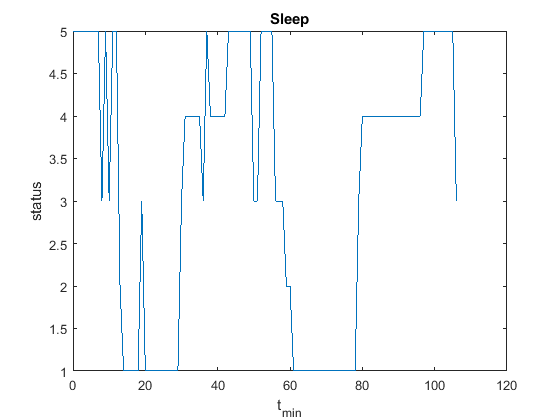

for i = 1 : numel(curr_data)
    if curr_data(i) == "qt"
       my_data(i) = 1;
    end
    if curr_data(i) == "qh"
       my_data(i) = 2;
    end
    if curr_data(i) == "tr"
       my_data(i) = 3;
    end
    if curr_data(i) == "al"
       my_data(i) = 4;
    end
    if curr_data(i) == "ah"
       my_data(i) = 5;
    end
    if curr_data(i) == "aw"
       my_data(i) = 6;
    end
end

plot(0:numel(my_data)-1, my_data)
title Sleep
xlabel t_m_i_n
ylabel status

time_step = 0.005

time_step = 0.0050

fs = 1 / time_step

fs = 200

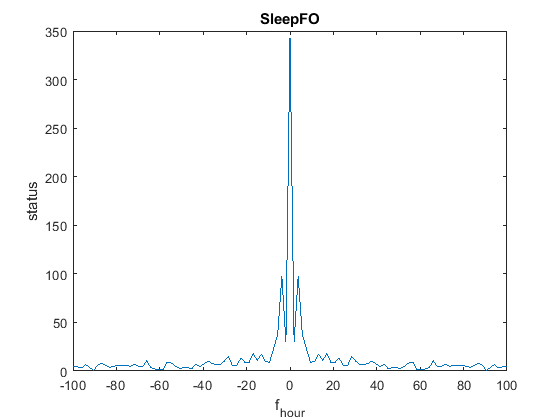

sleep_f_fo = linspace(-fs / 2, fs / 2, numel(my_data));
data_Fourier = fft(my_data);
data_Fourier_shift = fftshift(data_Fourier);
plot(sleep_f_fo, abs(data_Fourier_shift));
title SleepFO
xlabel f_h_o_u_r
ylabel status

حال ترتیب اختصاص ایندکس ها را جابجا می کنیم:

cd(fileparts(matlab.desktop.editor.getActiveFilename))
cd 'C:\Data\EEG Sleep Cycle'
read = load("data.mat")

read = struct with fields:
    data: {1×107 cell}


curr_data_2 = read.data

curr_data_2 = 1×107 cell array
    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'ah'}    {'tr'}    {'ah'}    {'ah'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'tr'}    {'ah'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'tr'}    {'qh'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'

my_data_2 = 1 : numel(curr_data_2)

my_data_2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


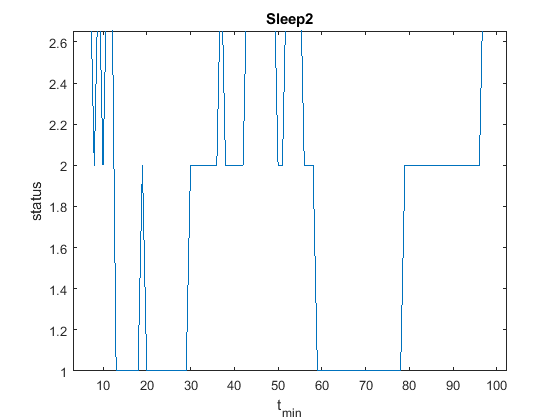

for i = 1 : numel(curr_data_2)
    if curr_data_2(i) == "qt"
       my_data_2(i) = 1;
    end
    if curr_data_2(i) == "qh"
       my_data_2(i) = 1;
    end
    if curr_data_2(i) == "tr"
       my_data_2(i) = 2;
    end
    if curr_data_2(i) == "al"
       my_data_2(i) = 2;
    end
    if curr_data_2(i) == "ah"
       my_data_2(i) = 3;
    end
    if curr_data_2(i) == "aw"
       my_data_2(i) = 3;
    end
end

plot(0:numel(my_data_2)-1, my_data_2)
title Sleep2
xlabel t_m_i_n
ylabel status

time_step = 0.005

time_step = 0.0050

fs = 1 / time_step

fs = 200

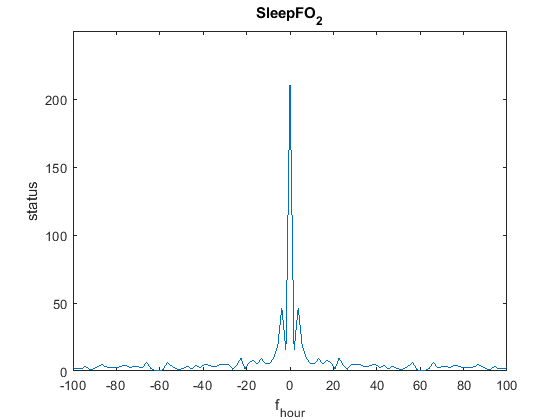

sleep_f_fo_2 = linspace(-fs / 2, fs / 2, numel(my_data_2));
data_Fourier_2 = fft(my_data_2);
data_Fourier_shift_2 = fftshift(data_Fourier_2);
plot(sleep_f_fo_2, abs(data_Fourier_shift_2));
title SleepFO_2
xlabel f_h_o_u_r
ylabel status

پس از این تغییر دو تعداد وضعیت ها تقسیم بر 2 شده و یکی شده اند در نتیجه تابع کمی جمع تز شده و جزییات کمتری نشان می دهد

و دقت کمتر شده ولی نتیجه بدون تغییر است.

## سوال سوم-پردازش صدا، موسیقی

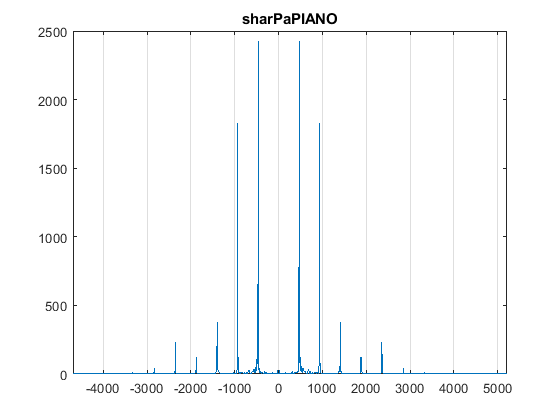

[y_a, fs_a] = audioread("C:\Data\Piano\piano_A.mp3");
[y_b, fs_b] = audioread("C:\Data\Piano\piano_B.mp3");
[y_d, fs_d] = audioread("C:\Data\Piano\piano_D.mp3");
[y_e, fs_e] = audioread("C:\Data\Piano\piano_E.mp3");
[y_f, fs_f] = audioread("C:\Data\Piano\piano_F.mp3");
[y_g, fs_g] = audioread("C:\Data\Piano\piano_G.mp3");

[y_a_sharp, fs_a_sharp] = audioread("C:\Data\Piano\piano_A_sharp.mp3");
[y_c_sharp, fs_c_sharp] = audioread("C:\Data\Piano\piano_C_sharp.mp3");
[y_d_sharp, fs_d_sharp] = audioread("C:\Data\Piano\piano_D_sharp.mp3");
[y_f_sharp, fs_f_sharp] = audioread("C:\Data\Piano\piano_F_sharp.mp3");
[y_g_sharp, fs_g_sharp] = audioread("C:\Data\Piano\piano_G_sharp.mp3");

[y_mid_c, fs_mid_c] = audioread("C:\Data\Piano\piano_middle_C.mp3");



len_a_sharp = length(y_a_sharp);
a_sharp_Fourier = (-len_a_sharp / 2 : len_a_sharp / 2 - 1) * (fs_a_sharp / len_a_sharp);

y_a_sharp_Fourier = fft(y_a_sharp);
y_shift_a_sharp_Fourier = fftshift(y_a_sharp_Fourier);

plot(a_sharp_Fourier, abs(y_shift_a_sharp_Fourier));

title sharPaPIANO;
xlim([-4500, 4500])

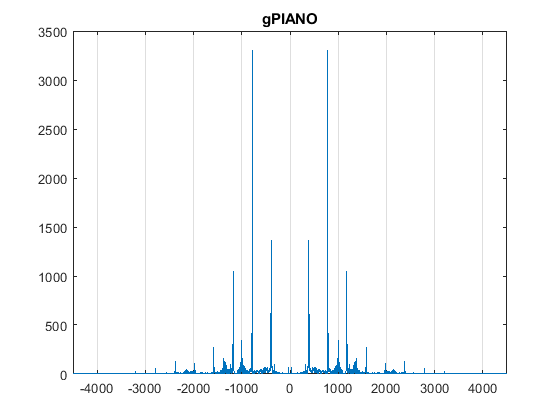




len_g = length(y_g);
g_Fourier = (-len_g / 2 : len_g / 2 - 1) * (fs_g / len_g);

y_g_Fourier = fft(y_g);
y_shift_g_Fourier = fftshift(y_g_Fourier);

plot(g_Fourier, abs(y_shift_g_Fourier));

title gPIANO;
xlim([-4500, 4500])


sound(y_a_sharp, fs_a_sharp);
sound(y_g, fs_g);

هر‌چه فرکانسِ یک صدا بیشتر شود (یعنی تعداد ارتعاش آن در واحد ثانیه بیشتر شود) صدا زیرتر می‌شود